% wmRod.mlx

% WAVE MOTION
%  Transverse Normal Modes of a vibrating rod 
%  Helmholtz Equation: eigenvalues and eigenfunctions
%  Spatial Wavefunction: Boundary Conditions
%   Fixed/Fixed: nodes at both ends
%   Fixed/Free:  node and antinode at ends
%   Free/Free:   antinodes at both ends  

% Ian Cooper
% email: matlabvisualphysics@gmail.com
% 200425 / Matlab version R2020a

% DOING PHYSICS WITH MATLAB 
%    http://www.physics.usyd.edu.au/teach_res/mp/mphome.htm
% Reference page for documentation and notes
%    http://www.physics.usyd.edu.au/teach_res/mp/doc/wmRod.htm
% Download Location
%    http://www.physics.usyd.edu.au/teach_res/mp/mscripts/
  

clear 
close all
clc


% INPUTS  =============================================================
% Boundary conditions:
%  fixed fixed BC = 1 (default)/ fixed free BC = 2 / free free BC = 3 
BC = 1

BC = 1


% Mode number for graphical output  m = 1,2,3, ...  
  m = 4

m = 4

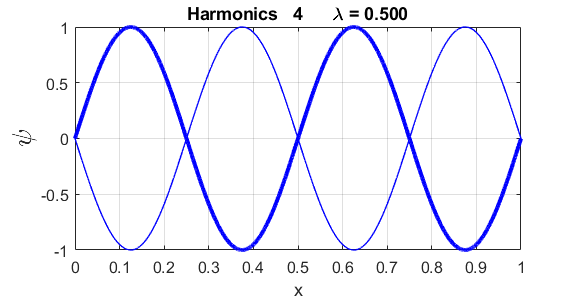


  
% Number of grid points
  N = 5599;
% Length of rod [m]
  L = 1;
  

% CALCULATIONS  ======================================================
% Spatial domain  [m]
  x = linspace(0,L,N+2);
  dx = x(2) - x(1);
  
% Eigenvalue Matrix A: eigenfunctions (eignFN) / eigenvalues (eignV) 
  off = ones(N-1,1);
  A = - diag(off,-1) + 2*eye(N) - diag(off,1) ;
  if BC == 2; A(N,N) = 1; end               % fixed free
  if BC == 3; A(1,1) = 1; A(N,N) = 1; end   % free free

  [eignFN, eignV] = eig(A);

% Apply boundary conditions (default: nodes at both ends)
% Harmonic modeN  
  modeN = m;  
  if BC == 2
     modeN = 2*m-1;    
  end
  if BC == 3
     m = m+1;
     modeN = m-1;
  end
  
% Spatial Wavefunction  
  psi = zeros(N+2,1);
  psi(2:N+1) = eignFN(:,m);
  psi = psi ./max(psi);

  if BC == 2
     psi(N+2)= psi(N+1);
  end
  
  if BC == 3
     psi(1) = psi(2); psi(N+2) = psi(N+1);
  end  
  
% Eigenvalue (coloumn vector)
  K = diag(eignV);
% Wavenumber (propagation constant) [1/m]
  k = sqrt(K(m))/dx;
% Wavelength [m]
  wL = 2*pi/k;
    

% GRAPHICS  ===========================================================  
figure(1)
  set(gcf,'units','normalized');
  set(gcf,'position',[0.02 0.1 0.30 0.25]);
  set(gcf,'color','w');
  
  plot(x,psi,'b','linewidth',3)
  hold on
  plot(x,-psi,'b','linewidth',1)
  grid on
  xlabel('x')
  txt = sprintf('Harmonics  %2.0f      \\lambda = %2.3f',modeN,wL);
  title(txt)
  set(gca,'xtick',0:0.1:1)
  set(gca,'fontsize',12)
  ylabel('\psi','fontsize',20)